Cargamos los datos medidos.

motor_data = load('C:\Users\miqui\OneDrive\University\4º 23-24\Realimentados\practica_motor\realizacion\motor_data\all_data.mat')

motor_data = struct with fields:
    motor00V: [1×1 Simulink.SimulationData.Dataset]
    motor01V: [1×1 Simulink.SimulationData.Dataset]
    motor02V: [1×1 Simulink.SimulationData.Dataset]
    motor03V: [1×1 Simulink.SimulationData.Dataset]
    motor04V: [1×1 Simulink.SimulationData.Dataset]
    motor05V: [1×1 Simulink.SimulationData.Dataset]
    motor06V: [1×1 Simulink.SimulationData.Dataset]
    motor07V: [1×1 Simulink.SimulationData.Dataset]
    motor08V: [1×1 Simulink.SimulationData.Dataset]
    motor09V: [1×1 Simulink.SimulationData.Dataset]
    motor10V: [1×1 Simulink.SimulationData.Dataset]
    motor11V: [1×1 Simulink.SimulationData.Dataset]
    motor12V: [1×1 Simulink.SimulationData.Dataset]


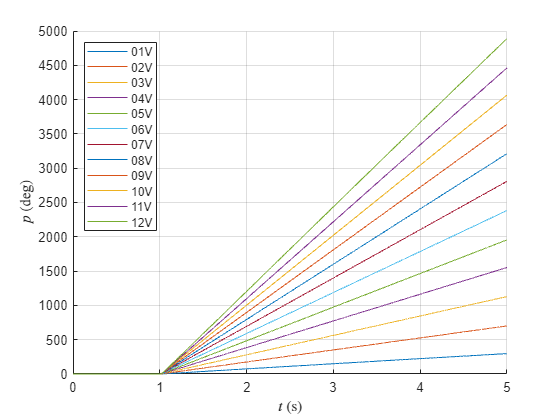

figure
hold on
for i = 1:12
    % Extracción de datos
    voltage = pad(num2str(i), 2, "left", '0');
    extracted = motor_data.(strcat('motor',voltage,'V')).getElement('Motor:1');
    positions = extracted.Values.Data;
    time = extracted.Values.Time;
    % Representación
    plot(time, positions, DisplayName=strcat(voltage,'V'))
    grid on
end
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$p$ (deg)', Interpreter='latex')
exportgraphics(gcf,'figuras\posicionLazoAbierto.pdf')

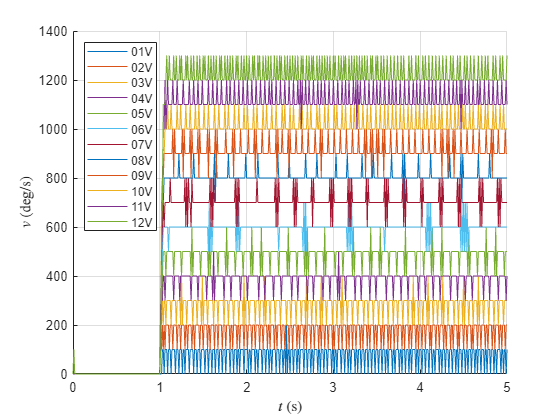

figure
hold on
for i = 1:12
    % Extracción de datos
    voltage = pad(num2str(i), 2, "left", '0');
    extracted = motor_data.(strcat('motor',voltage,'V')).getElement('Motor:2');
    positions = extracted.Values.Data;
    time = extracted.Values.Time;
    % Representación
    plot(time, positions, DisplayName=strcat(voltage,'V'))
    grid on
end
legend(Location="northwest")
xlabel('$t$ (s)', Interpreter='latex')
ylabel('$v$ (deg/s)', Interpreter='latex')
xlim([0 5])
exportgraphics(gcf,'figuras\velocidadLazoAbierto.pdf')